%тест1
format long;
n = 13;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans =   25.374932502995208


norm(x_qr - e)

ans =   68.845932419981196


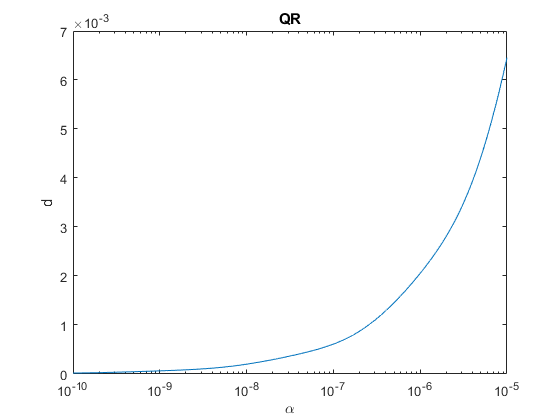

alpha = 1e-10;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      1.000000000000000e-10


disp('Который равен:');

Который равен:


m

m =      1.880529079197897e-05


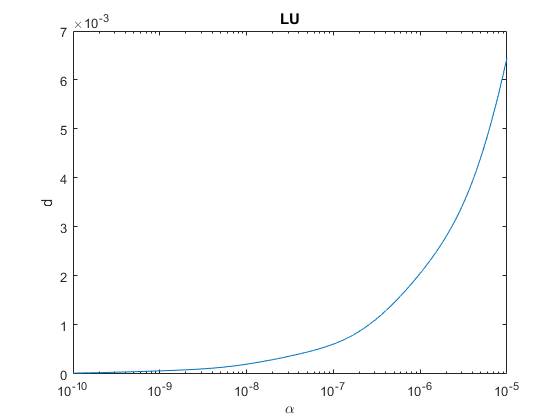

alpha = 1e-10;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      1.000000000000000e-10


disp('Который равен:');

Который равен:


m

m =      1.769461181587706e-05


%тест2
n = 17;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans =   10.166375241049424


norm(x_qr - e)

ans =   34.746405302809919


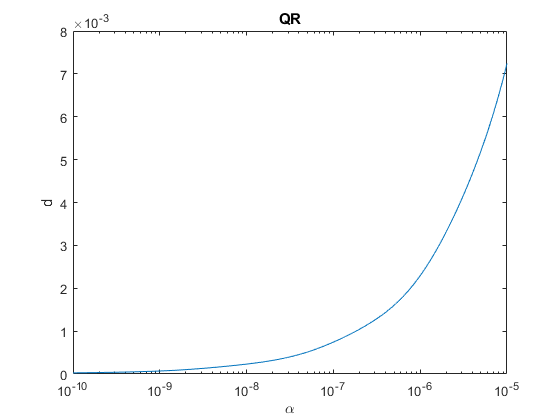

alpha = 1e-10;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      1.000000000000000e-10


disp('Который равен:');

Который равен:


m

m =      2.665042227534287e-05


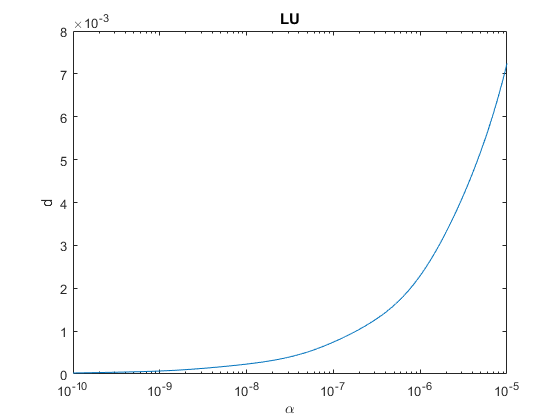

alpha = 1e-10;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      1.000000000000000e-10


disp('Который равен:');

Который равен:


m

m =      2.370237219334831e-05


%тест3
n = 23;
H = hilb(n);
e = ones(n,1);
b = H*e;
x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans =      1.662459485765179e+02


norm(x_qr - e)

ans =      2.100699074881522e+02


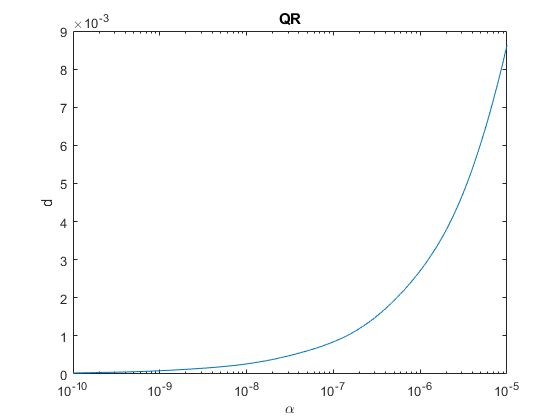

alpha = 1e-10;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      1.000000000000000e-10


disp('Который равен:');

Который равен:


m

m =      2.596577461815795e-05


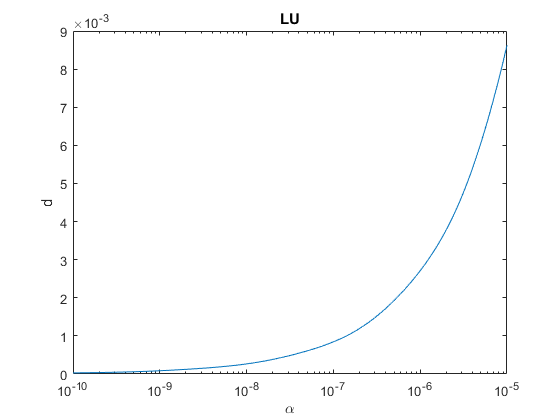

alpha = 1e-10;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans =      1.000000000000000e-10


disp('Который равен:');

Который равен:


m

m =      2.905762306331317e-05
